依赖[统一实验分析作图v17.1.1](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

Reinforced final network

预加载此脚本一次即可

[~,RSPdNtats]=TransferLearning.CoeffNtats("RSPd");

排序热图2

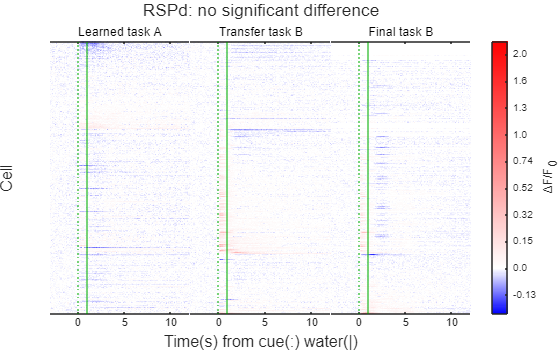

Colors=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);
Data=RSPdNtats.NTATS{:,:,["Learned4_cue1_water","Transfer_cue2_water","Final_cue2_water"]};
Data=Data(any(Data,2:3),:,:);
Layout=TransferLearning.AucGroupSortedHeatmap(Data,["Learned task A","Transfer task B","Final task B"],Colors,false);
title(Layout,'RSPd: no significant difference');
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
print(TransferLearning.ProjectPath('RSPdFinal.svg'),'-dsvg');